# "Finalized" filter test

This script is for testing out the final filters before incorporating them into the main data analysis functions!

% Get signals
fakemovement_mm = 0.01*exp(times_ms/5000).*sin(times_ms*5/1000) * 0.0;
x_pos_raw = x_pos + fakemovement_mm;
    filterwidth = 0.015;


% Filter attempts

% ~~ POSITION FILTER 1 (ORIGINAL) : S-G to remove noise, AND THEN filter out oscillations
    % with low-pass!
    % FILTER 0 : Emulating simulink model's filters (butter(6,0.6) -> mavge(10ms)),
    % to keep filter behaviour consistent between `mode_rawdata` settings
    if lower(mode_rawdata)=="raw"
        simulink_mavge_ms = 10;
        [bee,aye] = butter(6, 0.6);
        x_pos_simumean = movmean(filtfilt(bee,aye,x_pos_raw), simulink_mavge_ms);
    end
    % FILTER 1 : S-G -> moving average
    noise_period_ms = 135;
    x_sgfilt = sgolayfilt(x_pos_simumean,3,noise_period_ms);
    x_sgfilt2 = sgolayfilt(x_sgfilt,1,noise_period_ms);
    
    % FILTER 2 : Low-pass
    lowpass_cutoff_hz = filterwidth;
    filtershape   = 5;        % Lower = more Gaussian, higher = more rectangular
    [x_fil,~] = filter_lowpass(times_ms,x_sgfilt2,0,lowpass_cutoff_hz,filtershape,1,'Low-pass');

    % Calculate accelerations real quicky-like (in mm/s/s)
    x_vel = gradient(x_fil, times_s);
    x_afil = gradient(x_vel, times_s);

% ~~ POSITION FILTER 2 : "RAPID" filter
    % FILTER 0 : Emulating simulink model's filters (butter(6,0.6) -> mavge(????ms)),
    % to keep filter behaviour consistent between `mode_rawdata` settings--
    % BUT choosing a frequency such that an obvious periodic trend is still
    % present
    if lower(mode_rawdata)=="raw"
        simulink_mavge_ms = 10;
        [bee,aye] = butter(6, 0.6);
        x_pos_simumean2 = movmean(filtfilt(bee,aye,x_pos_raw), simulink_mavge_ms);
        % % Round off the remaining oscillations!
        % noise_period_ms = 10;
        % x_processed = sgolayfilt(x_pos_simumean2,2,noise_period_ms);
    end

    % FILTER 0 : `Resampling filter` to eliminate 100Hz noise!
    x_pos_resamp = resampling_filter(times_s, x_pos_simumean2,100);

    % FILTER 1 : S-G polyfit
    noise_period_ms = 151;
    % x_mavge = sgolayfilt(x_pos_resamp,1,noise_period_ms);
    x_fil_rapid = sgolayfilt(x_pos_resamp,2,noise_period_ms);

    % FILTER 2 : Low-pass
    lowpass_cutoff_hz = 0.014;
    filtershape   = 5;        % Lower = more Gaussian, higher = more rectangular
    [x_fil_rapid,~] = filter_lowpass(times_ms,x_fil_rapid,0,lowpass_cutoff_hz,filtershape,1,'Low-pass');

    % Calculate accelerations real quicky-like (in mm/s/s)
    x_vel_rapid = gradient(x_fil_rapid, times_s);
    x_acc_rapid = gradient(x_vel_rapid, times_s);
        % ~~ POSITION FILTER 2.5 : "ULTRA-RAPID" filter
            % Just for checking whether there are any movements that are
            % too sudden for even the "rapid" filter to keep up!
            % FILTER 1 : S-G polyfit
            ultrarapid_noise_period_ms = 11;
            x_fil_ultrarapid = sgolayfilt(x_pos_resamp,2,ultrarapid_noise_period_ms);
        
            % FILTER 2 : Low-pass
            % ultrarapid_lowpass_cutoff_hz = 0.165;
            % [x_fil_ultrarapid,~] = filter_lowpass(times_ms,x_fil_ultrarapid,0,ultrarapid_lowpass_cutoff_hz,filtershape,1,'Low-pass');
        
            % Calculate accelerations real quicky-like (in mm/s/s)
            x_vel_ultrarapid = gradient(x_pos_resamp, times_s);
            x_acc_ultrarapid = gradient(x_vel_ultrarapid, times_s);

            % Check for disagreements!
            toosudden_threshold_micron = 20; % In µm
            toosudden_idx = abs(x_fil_rapid - x_fil_ultrarapid)*1000 >= toosudden_threshold_micron;
            toosudden_idx = toosudden_idx & not(markfordeletion);   % Ignore data that'll be removed anyways
            
            % Warn wherever disagreements occur!
            transitions = diff([0, toosudden_idx', 0]);  % Nonzero wherever a cluster of 1's begins or ends
            cluster_starts = find(transitions == 1);
            cluster_ends   = find(transitions == -1) - 1;
            cluster_centers = round((cluster_starts + cluster_ends) / 2);
            
            % Print the clusters
            if sum(toosudden_idx)~=0
                fprintf('WARNING: File `_00%d.mf4` filters failed to match raw data near timestamps (in ms):', parse_mf4_number(str_fname));
                fprintf('%d ',round(times_ms(cluster_centers)));
            end

6622 17000 29906 36552 

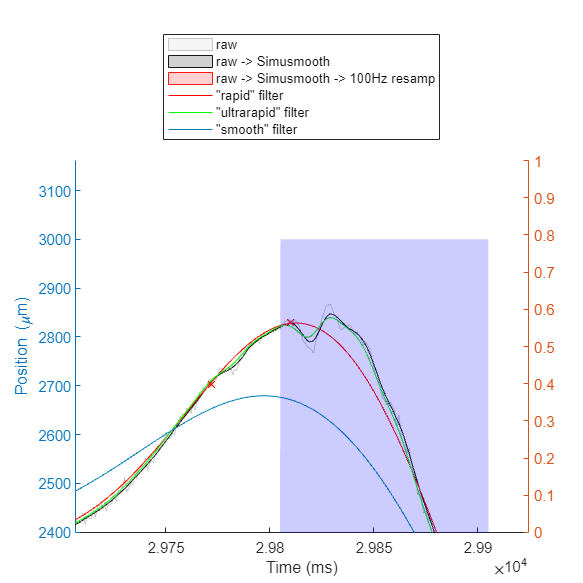


% ~~ POSITION FILTER 3 : "SMOOTH" filter
    % FILTER 0 : Emulating simulink model's filters (butter(6,0.6) -> mavge(????ms)),
    % to keep filter behaviour consistent between `mode_rawdata` settings--
    % BUT choosing a frequency such that an obvious periodic trend is still
    % present
    if lower(mode_rawdata)=="raw"
        simulink_mavge_ms = 10;
        [bee,aye] = butter(6, 0.6);
        x_pos_simumean2 = movmean(filtfilt(bee,aye,x_pos_raw), simulink_mavge_ms);
    end
    % FILTER 0 : `Resampling filter` to eliminate 100Hz noise!
    x_pos_resamp = resampling_filter(times_s, x_pos_simumean2,100);

    % FILTER 1 : `Resampling filter` to eliminate 9.60Hz noise!
    x_pos_resamp2 = resampling_filter(times_s, x_pos_resamp,9.60);
    % FILTER 1 : Other filter attempts
    % x_pos_resamp2 = movmean(x_pos_resamp,125);
    % x_pos_resamp2 = medfilt1(x_pos_resamp,1250,'truncate');
    % x_pos_resamp2 = sgolayfilt(x_pos_resamp,1,135);

    % FILTER 2: S-G -> Lowpass
    x_fil_smooth = sgolayfilt(x_pos_resamp2,1,125);

    % FILTER 2 : Low-pass
    lowpass_cutoff_hz = 0.015;
    filtershape   = 5;        % Lower = more Gaussian, higher = more rectangular
    [x_fil_smooth,newfilt] = filter_lowpass(times_ms,x_fil_smooth,0,lowpass_cutoff_hz,filtershape,1,'Low-pass');

    % Calculate accelerations real quicky-like (in mm/s/s)
    x_vel_smooth = gradient(x_fil_smooth, times_s);
    x_acc_smooth = gradient(x_vel_smooth, times_s);

% ~~~ POSITION FILTER 4: "SMOOTH+RAPID COMBINATION" filter
    % ~~~~ CALCULATE AREA BETWEEN "smooth" AND "rapid" CURVES ~~~~
    diffs = x_fil_rapid - x_fil_smooth;
    % % METHOD 1: Find where the difference changes sign (i.e. difference=0)
    % sign_diffs = diffs(1:end-1) .* diffs(2:end);
    % intersection_idx = find(sign_diffs <= 0);
    
    % METHOD 2: Find where the residuals are close to zero
    close_threshold_micron = 50;     % threshold for "disagreement" to be detected, in microns
    intersection_idx = find(abs(diffs*1000) <= close_threshold_micron);
    
    % Compute areas between curves
    segment_indices = arrayfun(@(i) intersection_idx(i):intersection_idx(i+1), 1:length(intersection_idx)-1, 'UniformOutput', false);
    segment_areas = cellfun(@(segment) abs(trapz(times_s(segment), (x_fil_rapid(segment) - x_fil_smooth(segment)))), segment_indices);
    
    % Convert areas to a 1D signal that can be displayed along time axis
    len = length(times_s);    % Number of entries in signal
    areas = zeros(size(times_ms));
    for i=1:length(intersection_idx)-1
        idx_start = intersection_idx(i);
        if i~=length(intersection_idx) 
            idx_end = intersection_idx(i+1)-1; 
        else 
            idx_end = len; 
        end
        % disp("Intersection "+num2str(i)+": "+num2str(idx_start)+" to "+num2str(idx_end))
        indices = idx_start:idx_end;
        areas(indices) = segment_areas(i);
    end
    
    % Let "disagreements" be visualize-able on a 1D plot
    disagreements = ones(size(times_s)); disagreements(intersection_idx) = 0;
    % Only allow "disagreements" where the area-between-curves is actually
    % significant
    area_threshold = 10 / 10000;
    disagreements(areas < area_threshold) = 0;
    
    % Parameters for the sine wave used for smoothing
    transition_time_ms = 80; % Duration of the sine wave transition in seconds
    transition_samples = round(transition_time_ms); % Number of samples for the transition
    strel = ones(1+2*transition_time_ms/8,1);   % 1D structuring element
    disagree_dilated = imdilate(disagreements,strel);
    half_sine_wave = (1-cos(linspace(0, 2*pi, transition_samples)))/2; % Sine wave, gradually rising and falling
    scales = conv(disagree_dilated,half_sine_wave,'same'); scales = scales/max(scales);
    
    % Final combination
    % x_acc_smooth = gradient(gradient(x_fil_smooth, times_s),times_s);
    % x_acc_rapid = gradient(gradient(x_fil_rapid, times_s),times_s);
    x_final =     (1-scales).*(x_fil_smooth) + (scales).*(x_fil_rapid); 
    x_afinal_v1 = (1-scales).*(x_acc_smooth) + (scales).*(x_acc_rapid); % BETTER VERSION.
    x_afinal_v2 = gradient(gradient(x_final, times_s),times_s); % DO NOT USE. The `scales` bit introduces artifacts in derivatives!
            % ^ JUSTIFICATION FOR THIS "CHOICE" OF X_AFINAL:
            % We want to take the best parts of both acceleration curves.
            % However, the "scales" vector introduces discontinuities in the
            % second derivative that we do NOT want; so we instead combine the
            % acceleration curves directly (as opposed to applying "scales" to
            % the filtered position curves AND THEN taking the second
            % derivative).
            % In a similar vein, the "scales" vector's weird discontinuities in
            % 2nd derivative means that our choice of acceleration curve cannot 
            % be used to "reconstruct" the final position curve.
            % The end result is that d2x/dx2 (x_final) and x_afinal are NOT THE
            % SAME, and we kinda just have to accept that.

% ~~~~~~~~~~~~~~~~~~~~
% ~~~~~ PLOTTING ~~~~~
% ~~~~~~~~~~~~~~~~~~~~

% Left axis: positions
        % Figure window size
        figwidth_px = 700; 
        figheight_px = 700;
        close all; figure; fig=gcf; fig.Position(3:4)=[figwidth_px,figheight_px];

        % Choose xlim
        if parse_mf4_number(str_fname)==0
            xlim([1e4, 1.1e4])
        elseif parse_mf4_number(str_fname)==17
            xlim([2.95e4, 3.05e4])   % Sudden acceleration
            % xlim([3.43e4,3.53e4])    % Gradual acceleration
            % xlim([0,1000]+17000)    % misc
            % xlim([0,100]+36500)    % misc
        end
        % Override xlim
        % xlim([1e4, 1.1e4])
        % xlim([2.95e4,3.05e4])
        % xlim([1.95e4,2.05e4]+10000)
        % xlim([1.99e4,2.01e4]+2000)
        % xlim([1.6,1.85]*10^4)
        % xlim([1.95e4,2.05e4]+2000)

yyaxis left
hold on
patchline(times_ms,x_pos_raw*1000, 'Color',[0, 0, 0, 0.2],'LineWidth',0.1,'LineStyle','-', 'DisplayName','raw');
patchline(times_ms,x_pos_simumean*1000, 'Color',[0, 0, 0, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','raw -> Simusmooth');
patchline(times_ms,x_pos_resamp*1000 , 'Color',[1, 0, 0, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','raw -> Simusmooth -> 100Hz resamp');
% patchline(times_ms,x_pos_resamp2*1000, 'Color',[0, 0.5, 0.7, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','raw -> Simusmooth -> resample TWICE');
% plot(times_ms,x_fil*1000      , 'Color',[0.7, 0.0, 0.8, 0.1],'LineWidth',0.1,'LineStyle','-', 'DisplayName','raw -> Simusmooth -> SG(3,135) -> mavge(3,135) (orig)');
plot(times_ms,x_fil_rapid*1000   , 'Color',[1, 0, 0, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','"rapid" filter');
plot(times_ms,x_fil_ultrarapid*1000,'Color',[0, 1, 0, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','"ultrarapid" filter');
plot(times_ms,x_fil_smooth*1000, 'Color',[0, 0.5, 0.7, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','"smooth" filter');
% plot(times_ms,x_final*1000, 'Color',[0.7, 0.2, 0.2, 0.9],'LineWidth',0.1,'LineStyle','--', 'DisplayName','COMBINED (FINAL)');
scatter(times_ms, x_pos*1000.*i_newratio_nan, 40, 'rX','DisplayName','New ratio', 'HandleVisibility','off')
hold off
ylabel("Position (\mum)")
xlabel("Time (ms)")
legend('Location','best')

% % Right axis: accelerations
% yyaxis right
% hold on
% % patchline(times_ms,x_afil*1000, 'Color',[0.9, 0.3, 0., 0.8],'LineWidth',0.1,'LineStyle','-', 'DisplayName','acc (orig)');
% % patchline(times_ms,x_afil2*1000, 'Color',[0.3, 0.8, 0, 0.6],'LineWidth',0.1,'LineStyle','-', 'DisplayName','acc (new)');
% patchline(times_ms,x_acc_rapid*1000, 'Color',[0.9, 0.3, 0., 0.8],'LineWidth',0.1,'LineStyle','-', 'DisplayName','acc, "rapid"');
% patchline(times_ms,x_acc_ultrarapid*1000, 'Color',[0.3, 0.9, 0., 0.8],'LineWidth',0.1,'LineStyle','-', 'DisplayName','acc, "ultrarapid"');
% patchline(times_ms,x_acc_smooth*1000, 'Color',[0.3, 0.3, 0.8, 0.6],'LineWidth',0.1,'LineStyle','-', 'DisplayName','acc, "smooth"');
% patchline(times_ms,x_afinal_v1*1000, 'Color',[0.1, 0.1, 0.9, 0.9],'LineWidth',0.5,'LineStyle',':', 'DisplayName','acc, "combined" FINAL');
% % patchline(times_ms,x_afinal_v2*1000, 'Color',[0.9, 0.1, 0.1, 0.9],'LineWidth',0.5,'LineStyle',':', 'DisplayName','acc, "combined" (doublegrad; do not use)');
% % scatter(times_ms, x_acc*1000.*i_newratio_nan, 40, 'rX','DisplayName','New ratio','HandleVisibility','off')
% patchline(times_ms,times_ms*0, 'Color',[0,0,0, 0.2],'LineWidth',0.5,'LineStyle','--', 'HandleVisibility','off');
% hold off
% ylabel("Acceleration (\mum/s/s)")

        % LEGEND
        if figwidth_px >= figheight_px*1.5
            legend_position = "eastoutside";
        elseif figheight_px >= figwidth_px*0.8
            legend_position = "northoutside";
        else
            legend_position = "best";
        end
        legend("Location",legend_position);


        % HIGHLIGHT REGIONS
        % yyaxis right
        plot_highlight_regions(times_ms, mark_spikes_z, [0,0,1,0.2]); % Z spikes
        plot_highlight_regions(times_ms, mark_spikes_xy, [1,0,0,0.2]); % XY spikes

        yyaxis left
a = 5

a =      5